Ts_roll = 1/100;
% Plant
A_roll = [-1/t_S, 0; r_S/I_x(1), 0];
b_roll = [1/t_S; 0];
c_roll = [0,1];
d_roll = 0;

sysC = ss(A_roll,b_roll,c_roll,d_roll);
sysD_roll = c2d(sysC,Ts_roll,'zoh');


Kp = 21

Kp = 21

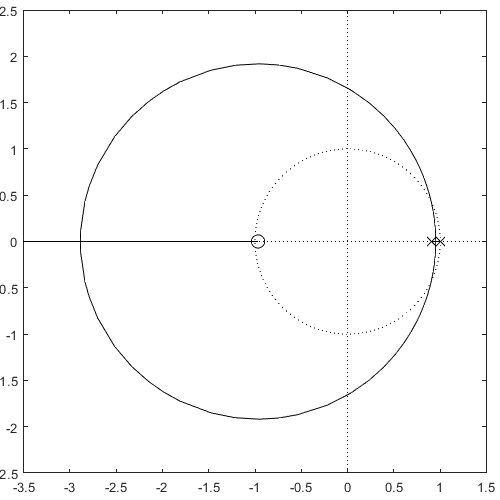

C_roll = pid(Kp,0,0,0,Ts_hor);
sysFB = feedback(C_roll*sysD_roll,1);
P_cl = rlocus(sysFB,1);
black_rlocus(sysD_roll,[])

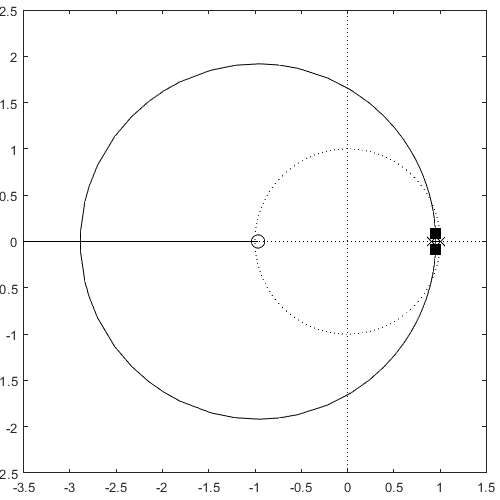

black_rlocus(C_roll*sysD_roll,P_cl)

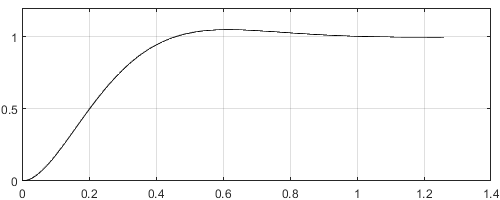

black_step(sysFB)